# Use Diagnostic Feature Designer for Fault Detection

Here, you use some of these signals in the **Diagnostic Feature Designer** app to extract features, which you then use to identify the number of broken rotor bars in the motor.

## Import Data into Diagnostic Feature Designer App

Open the **Diagnostic Feature Designer** app using the following command.

app = diagnosticFeatureDesigner;

You can then import the file ensemble datastore into the app by clicking the **New Session** button and selecting the `ens` variable from the list.

Once preliminary data is read by the app, make sure to uncheck the **Append data to file ensemble** option if you do not want to write new features or data back to the ensemble member files. When you are working with the smaller data set in this example, generating new features directly in memory is faster, so uncheck the option.

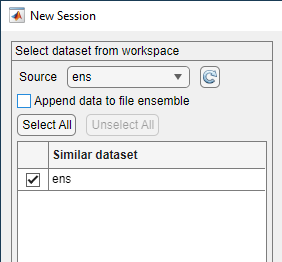

Alternatively, if the whole data set is small enough to fit into your computer's memory, then you can read it into a table object using the following command then import the table into the app directly.

% Working with in-memory data in the app. This may take a couple of minutes to
% run.
T = readall(ens)

T = 32×3 table
       Vib_acpi_env          Ia_env_ps         Health  
    __________________    ________________    _________

    {7601×1 timetable}    {25001×2 double}    "healthy"
    {7601×1 timetable}    {25001×2 double}    "healthy"
    {7601×1 timetable}    {25001×2 double}    "healthy"
    {7601×1 timetable}    {25001×2 double}    "healthy"
    {7601×1 timetable}    {25001×2 double}    "healthy"
    {7601×1 timetable}    {25001×2 double}    "healthy"
    {7601×1 timetable}    {25001×2 double}    "healthy"
    {7601×1 timetable}    {25001×2 double}    "healthy"
    {7601×1 timetable}    {25001×2 double}    "healthy"
    {7601×1 timetable}    {25001×2 double}    "healthy"
    {7601×1 timetable}    {25001×2 double}    "healthy"
    {7601×1 timetable}    {25001×2 double}    "healthy"
    {7601×1 timetable}    {25001×2 double}    "healthy"
    {7601×1 timetable}    {25001×2 double}

### Envelope Signal Data

Select the time-domain signals to import in the tree view of the **New Session** dialog. Here, you only use the synthetic signals, so uncheck `Ia` and `Vib_acpi`. Keep the envelope of the radial vibration speed on the driven side `Vib_acpi_env` checked; you do not need to modify it otherwise.

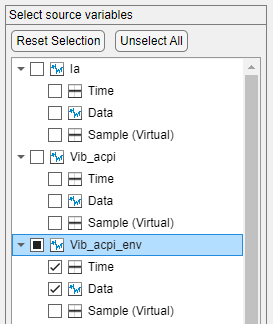

### Envelope Spectrum Data

Select the frequency-domain data to import. Keep the envelope spectrum of Phase A current `Ia_env_ps` selected and change its **Variable type** to `Spectrum`.

Specify `Col1` as an independent (frequency) variable with a corresponding 50 kHz sampling frequency.

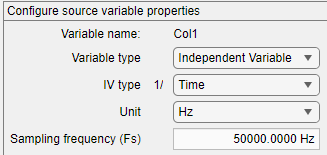

### Condition Variables

Finally, the condition variable of interest for fault classification is the `Health` variable, which corresponds to the number of broken rotor bars in the experiments. Ensure that its **Variable type** is `Condition Variable`.

Confirm the final ensemble specification and click **Import**.

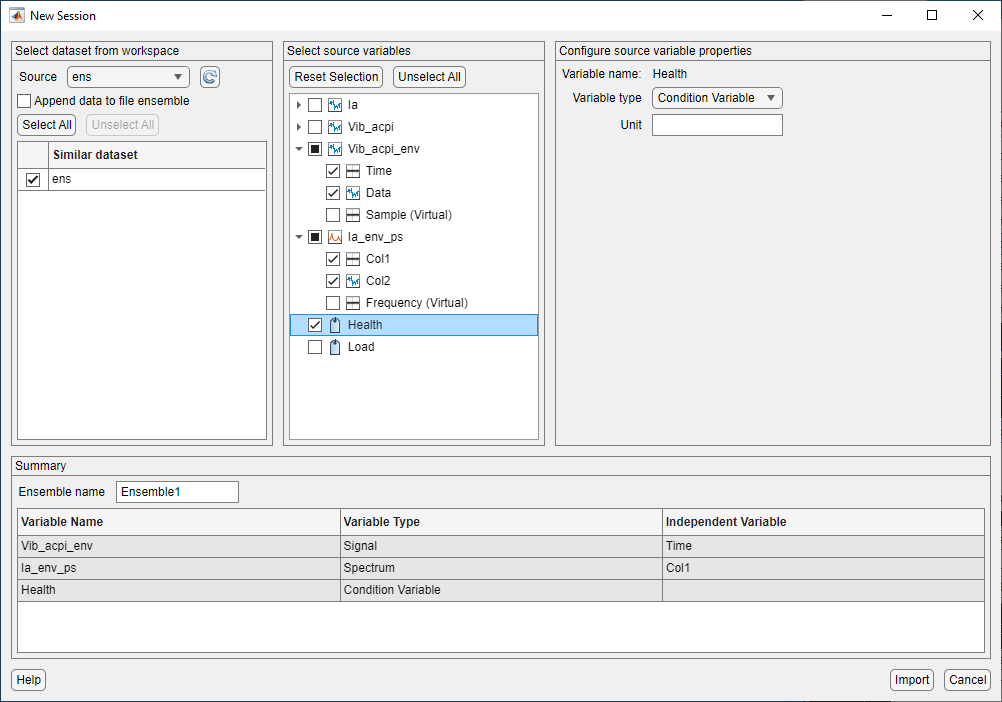

Once the file ensemble is imported, you can visualize the data by creating **Signal Trace** plots and grouping the plot colors based on the **Health** status of the experimental data. Note that reading all members of the file ensemble to produce plots and process the data might be time-consuming depending on the size and number of the data files that need to be read.

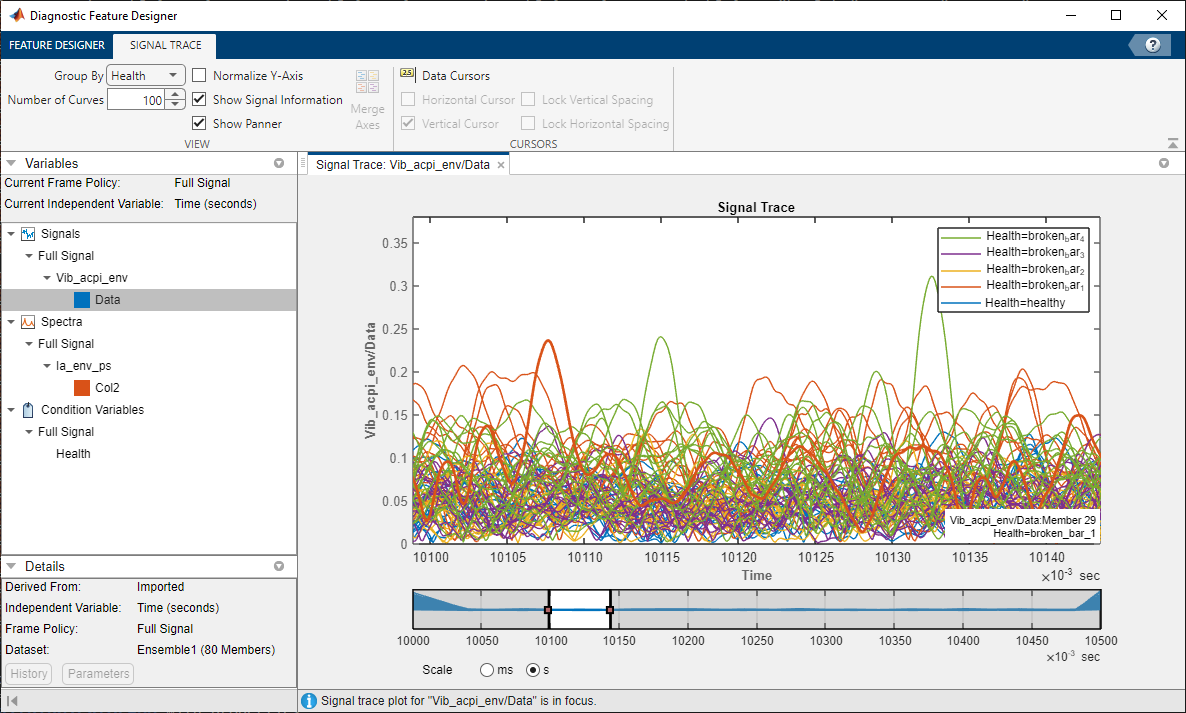

Note that the `getSignal` function used in `readMemberData` reads a portion of the signals from each member file after the initial transients due to motor startup have died down. In this case, the function loads only the data between 10.0 and 11.0 seconds

## Create Predictive Features

The **Auto Features** option is a fast way of creating a large number of features from available signals and ranking them according to their power in separating various health classes. For the imported time-domain signal `Vib_acpi_env`, apply the **Auto Features** option by selecting the signal in the Data Browser tree and clicking **Auto Features** on the **Feature Designer** tab.

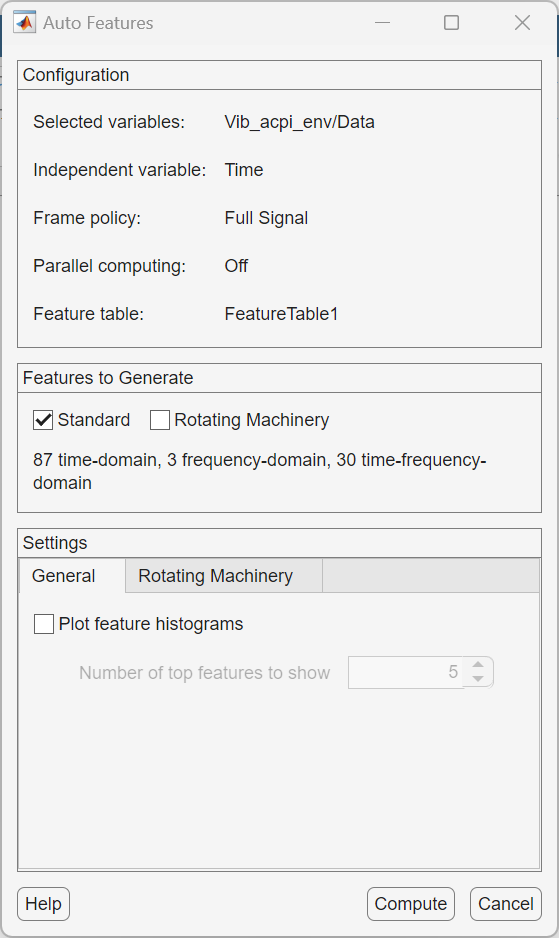

Clicking **Compute** generates a large number of features automatically and ranks them according their importance with respect to the **One-way ANOVA** criterion. This computation might take a few minutes to run.

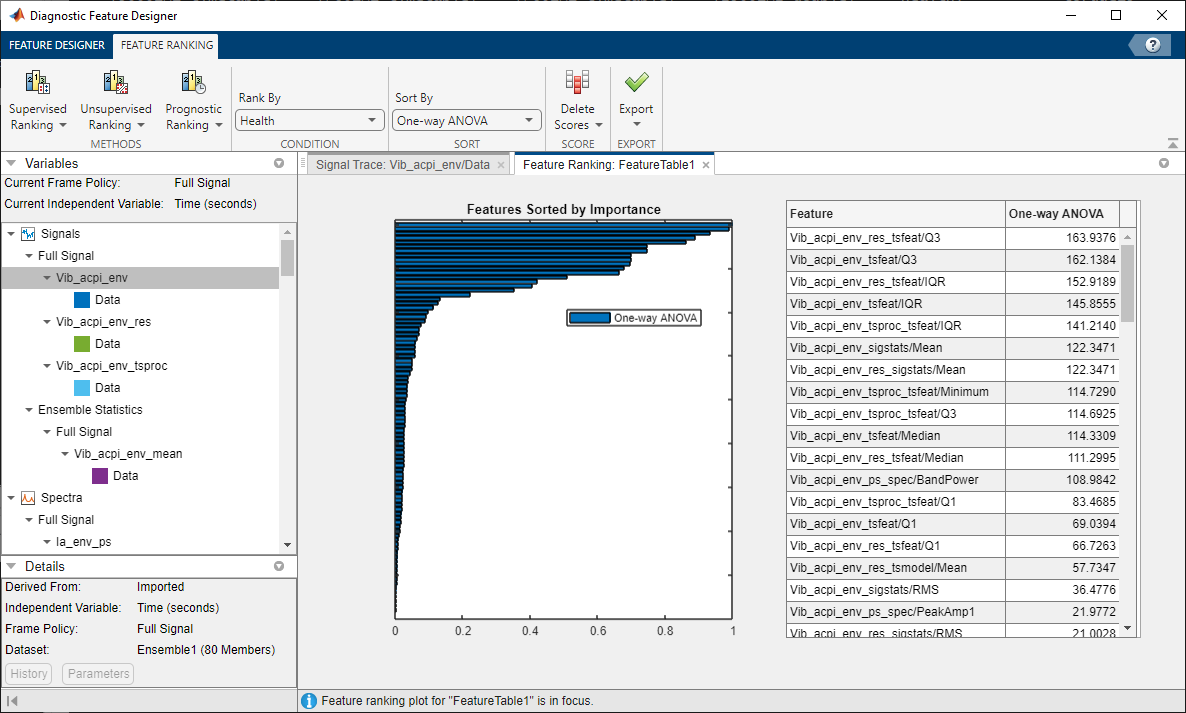

For generating features from envelope spectrum data, a more manual approach can yield more precise results. Select the `Ia_env_ps` signal in the Data Browser, and select **Custom Faults Features** under the **Frequency-Domain Features** menu. Select fault bands around a fundamental frequency of 60 Hz and its first 6 harmonics along with a sideband of 30 Hz to cover most of the spectral peaks in the envelope spectra. Use a fault band width of 10 Hz. Click **Apply** to generate features.

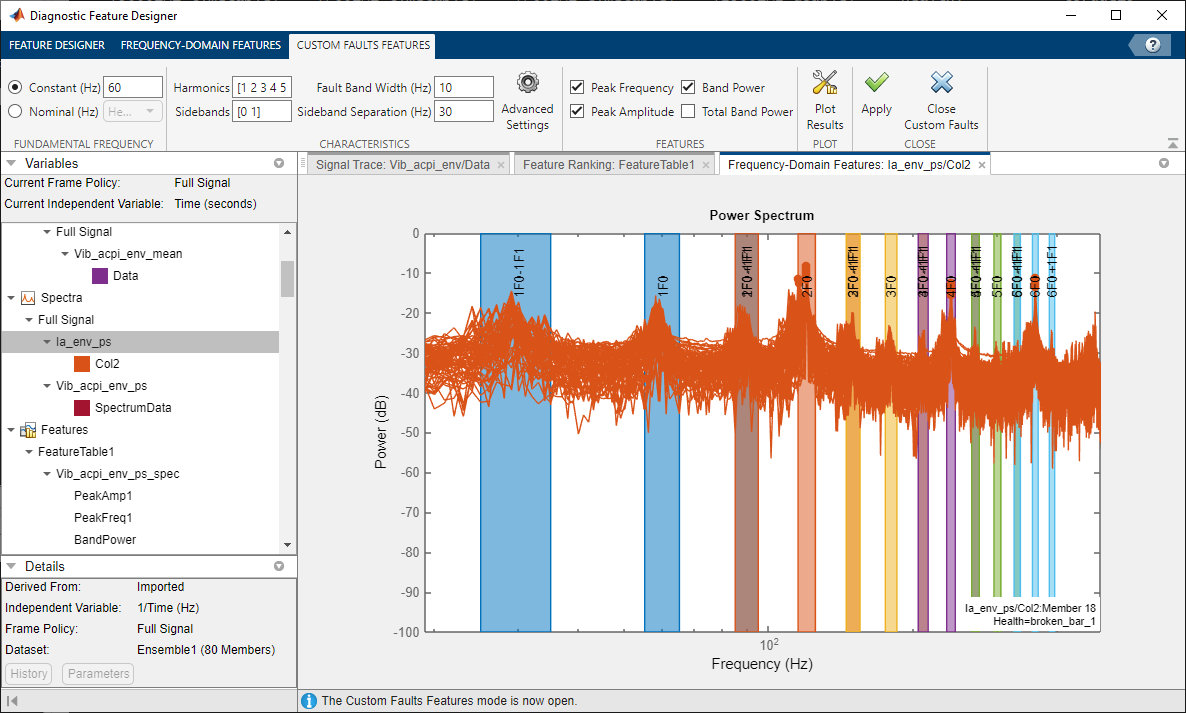

You have now generated a large number of features from the various electrical and vibration signals of the AC motor system.

## Rank Features

This process allows you to quickly create about 150 features both manually and automatically. The final ranking table indicates that the first 10 to 15 features, based on **One-way ANOVA** ranking, help classify the motors according to the number of broken rotor bars in them.

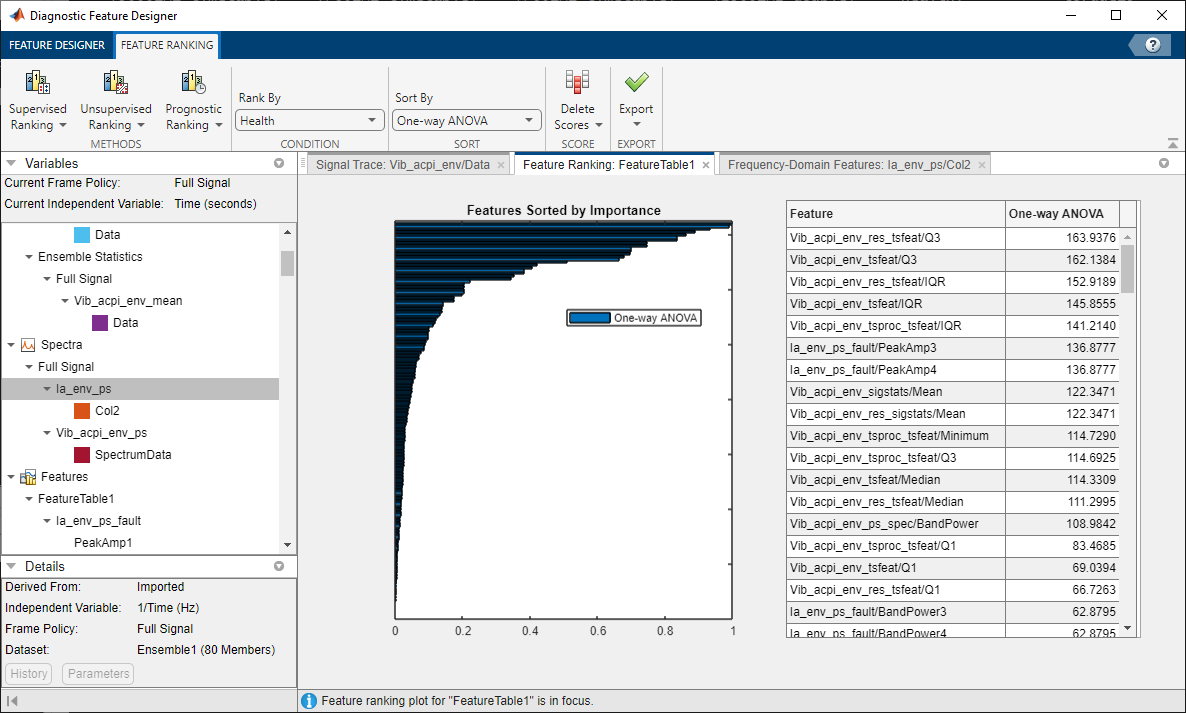

When fault bands and their corresponding names are difficult to identify, use the Peak Frequency feature to identify the corresponding fault band frequency/region.

## Export Features to Classification Learner App and Build a Tree Model

Export the top features from the **Diagnostic Feature Designer** app using **Export >** **Export Features To Classification Learner** on the **Feature Ranking** tab. Change **Select top features** to 10.

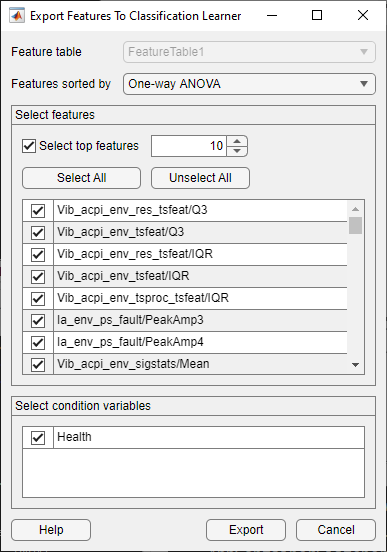

Click **Export** to start the **Classification Learner** app. 

## References

- Treml, Aline Elly, Rogério Andrade Flauzino, Marcelo Suetake, and Narco Afonso Ravazzoli Maciejewski. "Experimental database for detecting and diagnosing rotor broken bar in a threephase induction motor." IEEE Dataport, updated September 24, 2020, [https://dx.doi.org/10.21227/fmnm-bn95](https://dx.doi.org/10.21227/fmnm-bn95).

*Copyright 2022-2023 The MathWorks, Inc.*